# Plots

## Basic Plotting Functions

The `plot`  function has different forms, depending on the input arguments. If `y` is a vector, `plot(y)` produces a piecewise linear graph of the elements of `y` versus the index of the elements of `y`. If you specify two vectors as arguments, `plot(x,y)` produces a graph of `y`  versus `x`. For example, these statements use the colon operator to create a vector of `x` values ranging from 0 to 2π, compute the sine of these values, and plot the result:

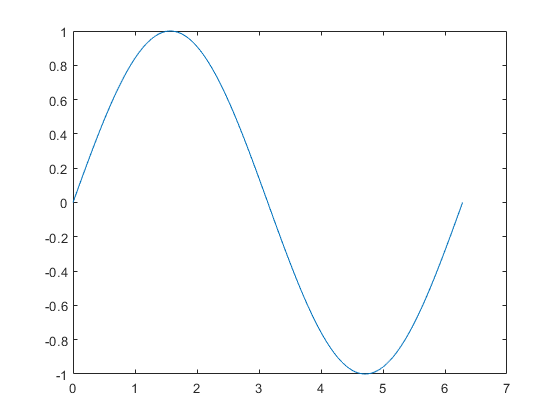

x = 0:pi/100:2*pi;
y = sin(x);
plot(x,y)

Now label the axes and add a title. The characters `\pi` create the symbol π. See “text strings” in the MATLAB Reference documentation for more symbols:

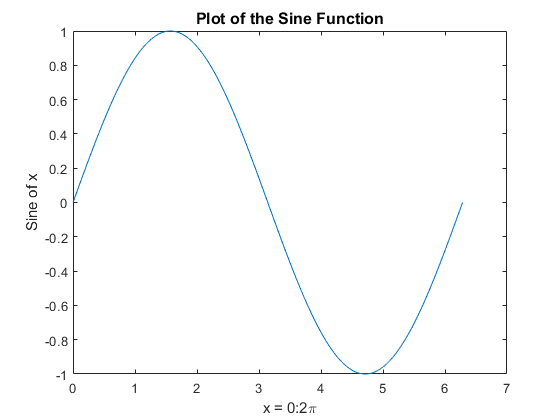

plot(x,y)
xlabel('x = 0:2\pi')
ylabel('Sine of x')
title('Plot of the Sine Function','FontSize',12)

### Multiple Data Sets in One Graph

Multiple `x`-`y`  pair arguments create multiple graphs with a single call to plot. MATLAB automatically cycles through a predefined (but user settable) list of colors to allow discrimination among sets of data. See the axes `ColorOrder` and `LineStyleOrder` properties. For example, these statements plot three related functions of `x`, with each curve in a separate distinguishing color:

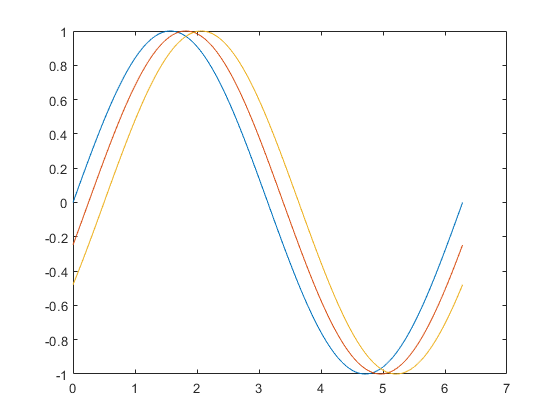

x = 0:pi/100:2*pi;
y = sin(x);
y2 = sin(x-.25);
y3 = sin(x-.5);
plot(x,y,x,y2,x,y3)

The `legend` command provides an easy way to identify the individual plots:

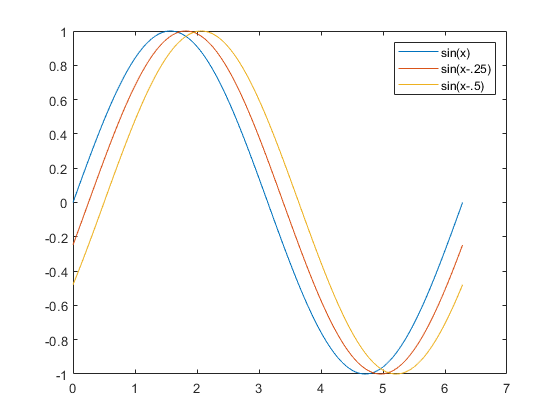

plot(x,y,x,y2,x,y3)
legend('sin(x)','sin(x-.25)','sin(x-.5)')

### Specifying Line Styles and Colors

It is possible to specify color, line styles, and markers (such as plus signs or circles) when you plot your data using the `plot` command:

- Color strings are `'c'`, `'m'`, `'y'`, `'r'`, `'g'`, `'b'`, `'w'`, and `'k'`. These correspond to cyan, magenta, yellow, red, green, blue, white, and black.

- Line style strings are `'-'` for solid, `'--'` for dashed, `':'` for dotted, and `'-.'` for dash-dot. Omit the line style for no line.

- The marker types are `'+'`, `'o'`, `'*'`, and `'x'`, and the filled marker types are `'s'` for square, `'d'` for diamond, `'^'` for up triangle, `'v'` for down triangle, `'>'` for right triangle, `'<'` for left triangle, `'p'` for pentagram, `'h'` for hexagram, and none for no marker.

### Plotting Lines and Markers

If you specify a marker type but not a line style, MATLAB draws only the marker. For example, `plot(x,y,'ks')` plots black squares at each data point, but does not connect the markers with a line.

The statement `plot(x,y,'r:+')` plots a red dotted line and places plus sign markers at each data point.

### Placing Markers at Every Tenth Data Point

You might want to use fewer data points to plot the markers than you use to plot the lines. This example plots the data twice using a different number of points for the dotted line and marker plots:

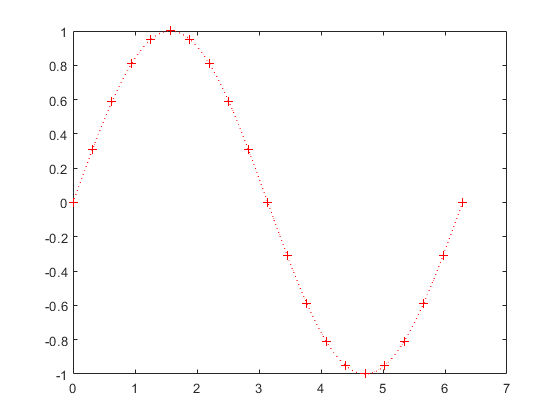

x1 = 0:pi/100:2*pi;
x2 = 0:pi/10:2*pi; 
plot(x1,sin(x1),'r:',x2,sin(x2),'r+')

### Graphing Imaginary and Complex Data

When the arguments to plot are complex, the imaginary part is ignored except when you pass plot a single complex argument. For this special case, the command is a shortcut for a graph of the real part versus the imaginary part. Therefore, `plot(Z)` where `Z` is a complex vector or matrix, is equivalent to `plot(real(Z),imag(Z))`. For example, 

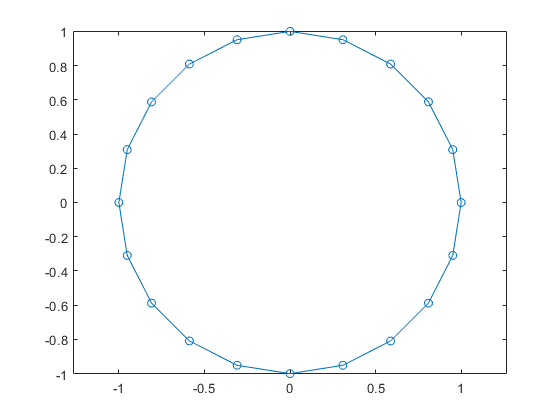

t = 0:pi/10:2*pi; 
plot(exp(1i*t),'-o')
axis equal

draws a 20-sided polygon with little circles at the vertices. The axis equal command makes the individual tick-mark increments on the $x$- and $y$-axes the same length, which makes this plot more circular in appearance.

### Adding Plots to an Existing Graph

The `hold` command enables you to add plots to an existing graph. When you type `hold on` MATLAB does not replace the existing graph when you issue another plotting command; it adds the new data to the current graph, rescaling the axes if necessary.

For example, these statements first create a contour plot of the `peaks` function, then superimpose a pseudocolor plot of the same function:

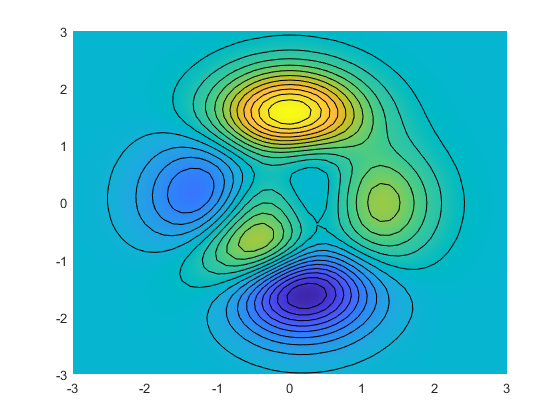

[x,y,z] = peaks;
pcolor(x,y,z)
shading interp
hold on
contour(x,y,z,20,'k')
hold off

The `hold on` command combines the `pcolor` plot with the `contour` plot in one figure.

### Figure Windows

Graphing functions automatically open a new figure window if there are no figure windows already on the screen. If a figure window exists, MATLAB uses that window for graphics output. If there are multiple figure windows open, MATLAB targets the one that is designated the “current figure” (the last figure used or clicked in).

To make an existing figure window the current figure, you can click the mouse while the pointer is in that window or you can type `figure(n)` where `n` is the number in the figure title bar. The results of subsequent graphics commands are displayed in this window.

To open a new figure window and make it the current figure, type `figure`.

When a figure already exists, most plotting commands clear the axes and use this figure to create the new plot. However, these commands do not reset figure properties, such as the background color or the colormap. If you have set any figure properties in the previous plot, you might want to use the `clf` command with the reset option, `clf reset` before creating your new plot to restore the figure’s properties to their defaults.

### Displaying Multiple Plots in One Figure

The `subplot` command enables you to display multiple plots in the same window or print them on the same piece of paper. Typing `subplot(m,n,p)` partitions the figure window into an `m`-by-`n` matrix of small subplots and selects the `p`th subplot for the current plot. The plots are numbered along the first row of the figure window, then the second row, and so on. For example, these statements plot data in four different subregions of the figure window:

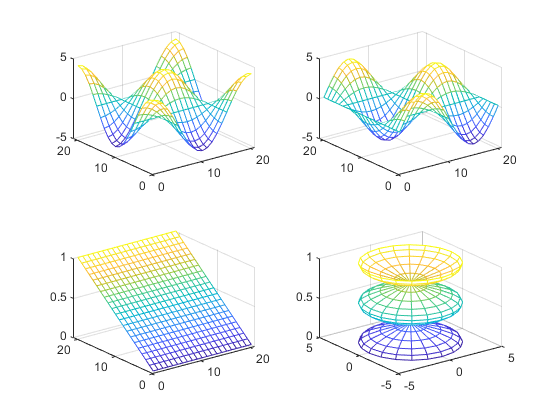

t = 0:pi/10:2*pi;
[X,Y,Z] = cylinder(4*cos(t)); 
subplot(2,2,1); mesh(X) 
subplot(2,2,2); mesh(Y) 
subplot(2,2,3); mesh(Z) 
subplot(2,2,4); mesh(X,Y,Z)

### Controlling the Axes

The `axis` command provides a number of options for setting the scaling, orientation, and aspect ratio of graphs.

By default, MATLAB finds the maxima and minima of the data and chooses the axis limits to span this range. The axis command enables you to specify your own limits:

or for three-dimensional graphs,

Use the command `axis auto` to reenable MATLAB automatic limit selection.

The `axis` command also enables you to specify a number of predefined modes. For example, `axis square` makes the $x$-axis and $y$-axis the same length. `axis equal` makes the individual tick mark increments on the $x$-axes and $y$-axes the same length. This means

followed by either `axis square` or `axis equal` turns the oval into a proper circle. `axis auto normal` returns the axis scaling to its default automatic mode.

#### Setting Axis Visibility

You can use the `axis` command to make the axis visible or invisible. `axis` on makes the axes visible. This is the default. `axis off` makes the axes invisible.

#### Setting Grid Lines

The `grid` command toggles grid lines on and off. The statement `grid on` turns the grid lines on, and `grid off` turns them back off again.

#### Adding Axis Labels and Titles

The `xlabel`, `ylabel`, and `zlabel` commands add $x$-, $y$-, and $z$-axis labels. The title command adds a title at the top of the figure and the text function inserts text anywhere in the figure.

You can produce mathematical symbols using LaTeX notation in the text string, as the following example illustrates:

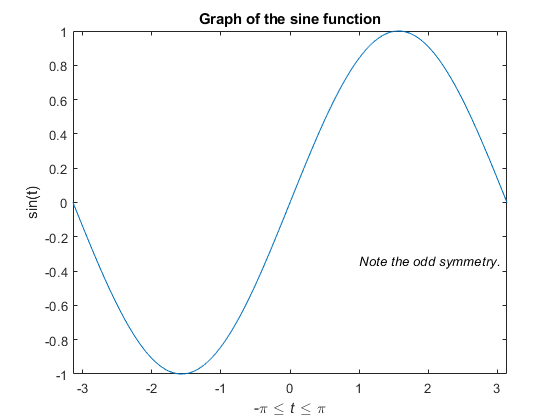

figure
t = -pi:pi/100:pi;
y = sin(t);
plot(t,y)
axis([-pi pi -1 1])
xlabel('-\pi \leq {\itt} \leq \pi')
ylabel('sin(t)')
title('Graph of the sine function')
text(1,-1/3,'{\itNote the odd symmetry.}')

Note that the location of the text string is defined in axes units (i.e., the same units as the data). See the `annotation` function for a way to place text in normalized figure units.

### Saving Figures

Save a figure by selecting **Save** from the **File** menu to display a Save dialog box. MATLAB saves the data it needs to recreate the figure and its contents (i.e., the entire graph) in a file with a **`.fig`** extension.

To save a figure using a standard graphics format, such as `SVG` or `PNG`, for use with other applications, select **Export Setup** from the **File** menu. You can also save from the command line—use the `saveas` command, including any options to save the figure in a different format.

#### Saving Workspace Data

You can save the variables in your workspace by selecting **Save Workspace As** from the figure **File** menu. You can reload saved data using the **Import Data** item in the figure **File** menu. MATLAB supports a variety of data file formats, including MATLAB data files, which have a `.mat` extension.

#### Generating M-Code to Recreate a Figure

You can generate MATLAB code that recreates a figure and the graph it contains by selecting **Generate M-File** from the figure **File** menu. This option is particularly useful if you have developed a graph using plotting tools and want to create a similar graph using the same or different data.

## Creating Mesh and Surface Plots

MATLAB defines a surface by the $z$-coordinates of points above a grid in the $x$-$y$ plane, using straight lines to connect adjacent points. The `mesh` and `surf` plotting functions display surfaces in three dimensions. `mesh` produces wireframe surfaces that color only the lines connecting the defining points. `surf` displays both the connecting lines and the faces of the surface in color.

### Visualizing Functions of Two Variables

To display a function of two variables, $z = f\left(x,y\right)$,

- Generate `X` and `Y` matrices consisting of repeated rows and columns, respectively, over the domain of the function.

- Use `X` and `Y` to evaluate and graph the function.

The `meshgrid`  function transforms the domain specified by a single vector or two vectors `x` and `y` into matrices `X` and `Y` for use in evaluating functions of two variables. The rows of `X` are copies of the vector `x` and the columns of `Y` are copies of the vector `y`.

This example evaluates and graphs the two-dimensional $sinc$ function, $\frac{sin\left(r\right)}{r}$ , between the $x$ and $y$ directions. `R` is the distance from the origin, which is at the center of the matrix. Adding `eps` (a MATLAB command that returns a small floating-point number) avoids the indeterminate $\frac{0}{0}$ at the origin:

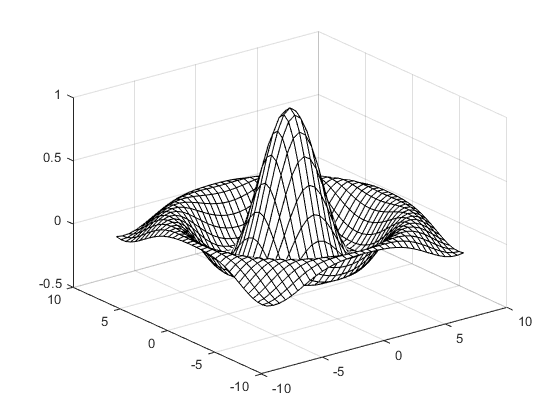

figure
[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R; 
mesh(X,Y,Z,'EdgeColor','black')

By default, MATLAB colors the mesh using the current colormap. However, this example uses a single-colored mesh by specifying the `EdgeColor` surface property.

You can create a mesh with see-through faces by disabling hidden line removal: `hidden off`.

### Colored Surface Plots

A `surface` plot is similar to a `mesh` plot except that MATLAB colors the rectangular faces of the surface. The color of each face is determined by the values of `Z` and the colormap (a colormap is an ordered list of colors). These statements graph the $sinc$ function as a surface plot, specify a colormap, and add a color bar to show the mapping of data to color:

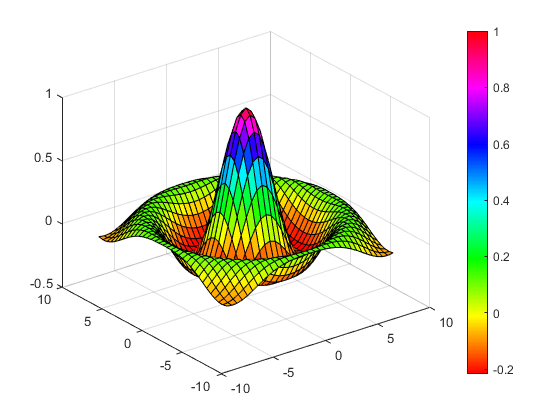

surf(X,Y,Z)
colormap hsv
colorbar

### Making Surfaces Transparent

You can make the faces of a surface transparent to a varying degree. Transparency (referred to as the alpha value) can be specified for the whole object or can be based on an `alphamap`, which behaves similarly to colormaps. For example,

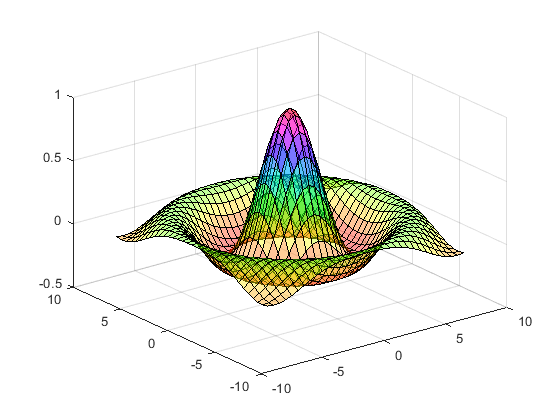

surf(X,Y,Z)
colormap hsv 
alpha(.4)

produces a surface with a face alpha value of 0.4. Alpha values range from 0 (completely transparent) to 1 (not transparent).

### Illuminating Surface Plots with Lights

Lighting is the technique of illuminating an object with a directional light source. In certain cases, this technique can make subtle differences in surface shape easier to see. Lighting can also be used to add realism to three-dimensional graphs.

This example uses the same surface as the previous examples, but colors it red and removes the mesh lines. A light object is then added to the left of the “camera” (the camera is the location in space from where you are viewing the surface):

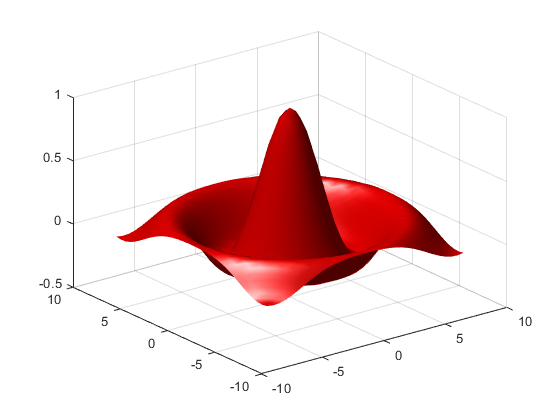

surf(X,Y,Z,'FaceColor','red','EdgeColor','none')
camlight left
lighting phong

## Plotting Image Data

Two-dimensional arrays can be displayed as images, where the array elements determine brightness or color of the images. For example, the statements

load durer
whos

  Name               Size               Bytes  Class                                  Attributes

  R                 33x33                8712  double                                           
  X                648x509            2638656  double                                           
  Y                 33x33                8712  double                                           
  Z                 33x33                8712  double                                           
  ans                1x1                    8  double                                           
  caption            2x28                 112  char                                             
  h                  0x0                    0  matlab.graphics.GraphicsPlaceholder              
  hax                1x1                    0  matlab.graphics.axis.Axes                        
  hfig               1x1                    0  matlab.ui.Figure                                 
  map              128x3     

load the file `durer.mat`, adding three variables to the workspace. The matrix `X` is a 648-by-509 matrix and `map` is a 128-by-3 matrix that is the colormap for this image.

MAT-files, such as `durer.mat`, are binary files that can be created on one platform and later read by MATLAB on a different platform.

The elements of `X` are integers between 1 and 128, which serve as indices into the colormap, `map`. Then

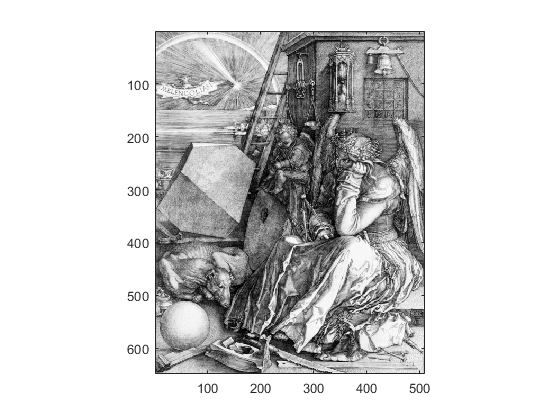

image(X)
colormap(map)
axis image

reproduces Albrecht Dürer’s etching.

A high-resolution scan of the magic square in the upper-right corner is available in another file.

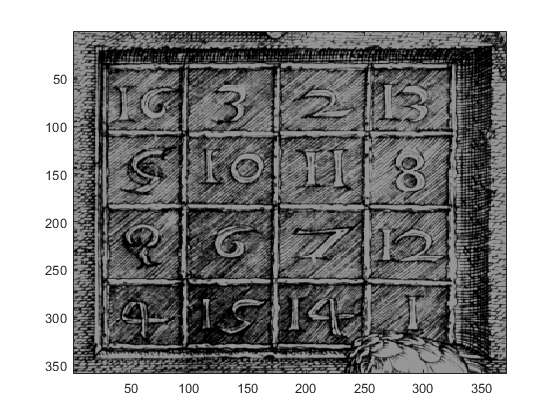

load detail
image(X)

The statement

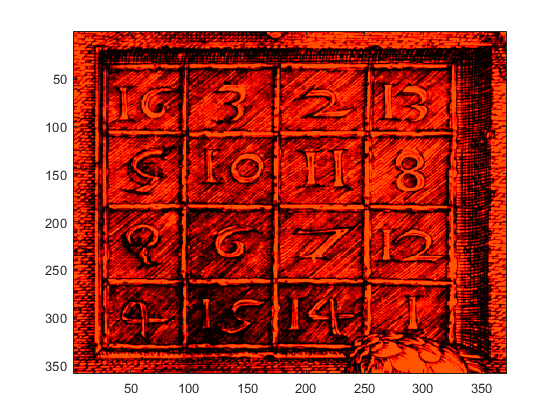

colormap(hot)

adds some 21st century colorization to the 16th century etching. The function `hot` generates a colormap containing shades of reds, oranges, and yellows. Typically, a given image matrix has a specific colormap associated with it.

### Reading and Writing Images

You can read standard image files (`TIFF`, `JPEG`, `BMP`, etc.) into MATLAB using the `imread` function. The type of data returned by imread depends on the type of image you are reading.

You can write MATLAB data to a variety of standard image formats using the `imwrite` function.

## Handle Graphics

Handle Graphics refers to a system of graphics objects that MATLAB uses to implement graphing and visualization functions. Each object created has a fixed set of properties. You can use these properties to control the behavior and appearance of your graph.

When you call a plotting function, MATLAB creates the graph using various graphics objects, such as a figure window, axes, lines, text, and so on. MATLAB enables you to query the value of each property and set the values of most properties.

For example, the following statement creates a figure with a white background color and without displaying the figure toolbar:

figure('Color','white','Toolbar','none')

### Using the Handle

Whenever MATLAB creates a graphics object, it assigns an identifier (called a handle) to the object. You can use this handle to access the object’s properties with the set and get functions. For example, the following statements create a graph and return a handle to a lineseries object in `h`:

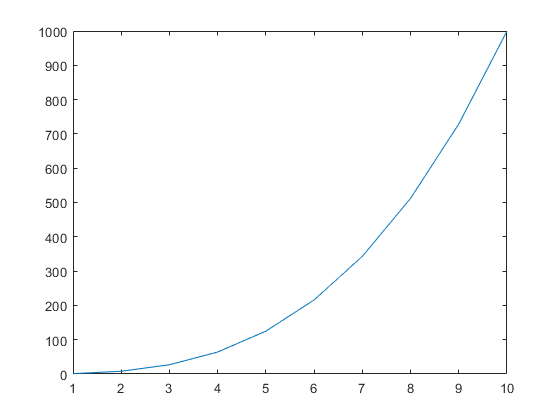

h =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10]
              YData: [1 8 27 64 125 216 343 512 729 1000]
              ZData: [1×0 double]

  Show all properties


x = 1:10;
y = x.^3;
h = plot(x,y)

You can use the handle `h` to set the properties of the lineseries object. For example, you can set its `Color` property:

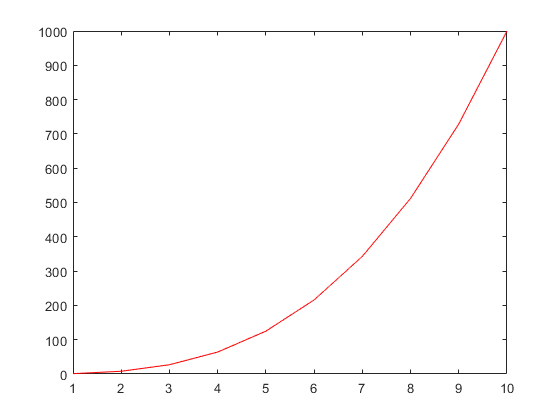

set(h,'Color','red')

You can also specify properties when you call the plotting function:

h = plot(x,y,'Color','red');

You can also query the lineseries properties:

get(h,'LineWidth')

ans = 0.5000

Use the handle to see what properties a particular object contains:

get(h)

    AlignVertexCenters: 'off'
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: 'off'
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: 'on'
                 Color: [1 0 0]
             ColorMode: 'manual'
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: 'on'
         Interruptible: 'on'
              LineJoin: 'round'
             LineStyle: '-'
         LineStyleMode: 'auto'
             LineWidth: 0.5000
                Marker: 'none'
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
         MarkerIndices: [1 2 3 4 5 6 7 8 9 10]
            MarkerMode: 'auto'
            MarkerSize: 6
                Parent: [1×1 Axes]
         PickableParts: 'visible'
              Selected: 'off'
    SelectionH

### Graphics Objects

Graphics objects are the basic elements used to display graphs and user interface components. These objects are organized into a hierarchy.

When you call a function to create a graph, MATLAB creates a hierarchy of graphics objects. For example, calling the `plot` function creates the following graphics objects:

- Lineseries plot objects — Represent the data passed to the `plot` function.

- Axes — Provide a frame of reference and scaling for the plotted lineseries. 

- Text — Label the axes tick marks and are used for titles and annotations. 

- Figures — Are the windows that contain axes toolbars, menus, etc.

Different types of graphs use different objects to represent data; however, all data objects are contained in axes and all objects (except root) are contained in figures.

The root is an abstract object that primarily stores information about your computer or MATLAB state. You cannot create an instance of the root object.

This table lists functions commonly used when working with objects.

**Function                   Purpose**

`allchild`                   Find all children of specified objects.

`ancestor`                   Find ancestor of graphics object.

`copyobj`                     Copy graphics object.

`delete`                       Delete an object.

`findall `                   Find all graphics objects (including hidden handles).

`findobj`                     Find the handles of objects having specified property values.

`gca`                             Return the handle of the current axes.

`gcf`                             Return the handle of the current figure.

`gco`                             Return the handle of the current object.

`get`                             Query the values of an object’s properties.

`ishandle`                   True if the value is a valid object handle.

`set`                             Set the values of an object’s properties.

### Setting Object Properties

All object properties have default values. However, you might find it useful to change the settings of some properties to customize your graph. There are two ways to set object properties:

- Specify values for properties when you create the object. 

- Set the property value on an object that already exists.

To modify the property values of existing objects, you can use the `set` command or the **Property Editor** of the **View** menu.

Most plotting functions return the handles of the objects that they create. So you can modify the objects using the `set` command. For example, these statements plot a 5-by-5 matrix (creating five lineseries, one per column), and then set the `Marker` property to a `square` and the `MarkerFaceColor` property to `green`:

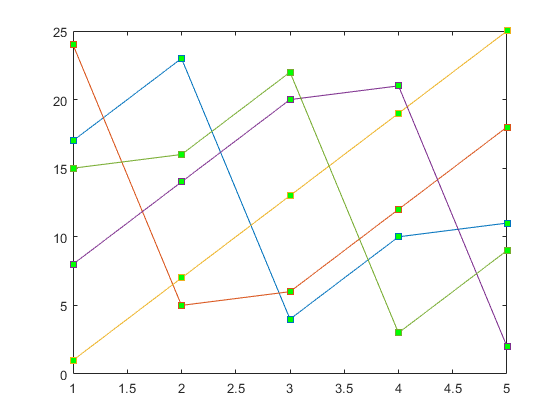

h = plot(magic(5)); 
set(h,'Marker','s','MarkerFaceColor','g')

In this case, `h` is a vector containing five handles, one for each of the five lineseries in the graph. The `set` statement sets the `Marker` and `MarkerFaceColor` properties of all lineseries to the same values.

If you want to set the properties of each lineseries to a different value, you can use cell arrays to store all the data and pass it to the set command.  Suppose you want to add different markers to each lineseries and color the marker’s face color the same color as the lineseries. You need to define two cell arrays—one containing the property names and the other containing the desired values of the properties.

The `prop_name` cell array contains two elements: 

prop_name(1) = {'Marker'};
prop_name(2) = {'MarkerFaceColor'};

The `prop_values` cell array contains 10 values: five values for the Marker property and five values for the `MarkerFaceColor` property. Notice that `prop_values` is a two-dimensional cell array. The first dimension indicates which handle in `h` the values apply to and the second dimension indicates which property the value is assigned to:

prop_values(1,1) = {'s'}; prop_values(1,2) = {get(h(1),'Color')}; 
prop_values(2,1) = {'d'}; prop_values(2,2) = {get(h(2),'Color')}; 
prop_values(3,1) = {'o'}; prop_values(3,2) = {get(h(3),'Color')}; 
prop_values(4,1) = {'p'}; prop_values(4,2) = {get(h(4),'Color')}; 
prop_values(5,1) = {'h'}; prop_values(5,2) = {get(h(5),'Color')};

The `MarkerFaceColor` is always assigned the value of the corresponding line’s color (obtained by getting the lineseries `Color` property with the `get` command).

After defining the cell arrays, call set to specify the new property values:

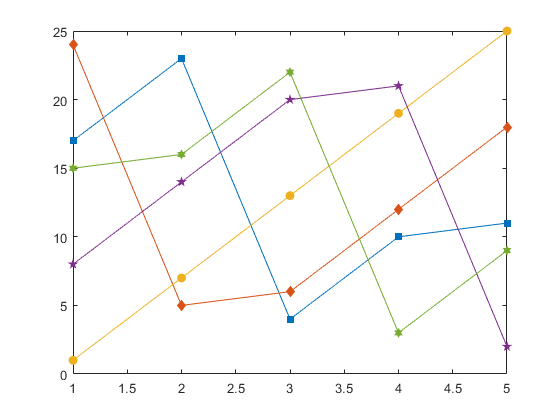

set(h,prop_name,prop_values)

### Specifying the Axes or Figure

MATLAB always creates an axes or figure if one does not exist when you issue a plotting command. However, when you are creating a graphics M-file, it is good practice to explicitly create and specify the parent axes and figure, particularly if others will use your program. Specifying the parent prevents the following problems:

- Your M-file overwrites the graph in the current figure. Note that a figure becomes the current figure whenever a user clicks it.

- The current figure might be in an unexpected state and not behave as your program expects.

The following example shows a simple M-file that plots a function and the mean of the function over the specified range:

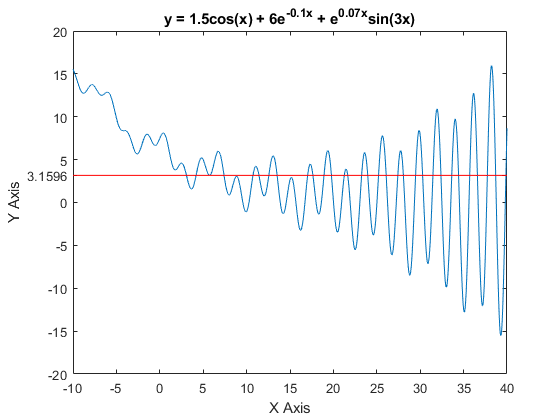

x = -10:.005:40;
y = 1.5*cos(x) + 6*exp(-.1*x) + exp(.07*x).*sin(3*x); 
ym = mean(y);
hfig = figure('Name','Function and Mean', 'Pointer','crosshair');
hax = axes('Parent',hfig);
plot(hax,x,y)
hold on
plot(hax,[min(x) max(x)],[ym ym],'Color','red') 
hold off
ylab = get(hax,'YTick');
set(hax,'YTick',sort([ylab ym]))
title ('y = 1.5cos(x) + 6e^{-0.1x} + e^{0.07x}sin(3x)') 
xlabel('X Axis')
ylabel('Y Axis')

### Finding the Handles of Existing Objects

The `findobj` function enables you to obtain the handles of graphics objects by searching for objects with particular property values. With `findobj` you can specify the values of any combination of properties, which makes it easy to pick one object out of many. `findobj` also recognizes regular expressions (regexp).

For example, you might want to find the blue line with square marker having blue face color. You can also specify which figures or axes to search, if there are more than one. The following four sections provide examples illustrating how to use `findobj`.

#### Finding All Objects of a Certain Type

Because all objects have a `Type` property that identifies the type of object, you can find the handles of all occurrences of a particular type of object. For example,

finds the handles of all patch objects.

#### Finding Objects with a Particular Property

You can specify multiple properties to narrow the search. For example,

finds the handles of all red dotted lines.

#### Limiting the Scope of the Search

You can specify the starting point in the object hierarchy by passing the handle of the starting figure or axes as the first argument. For example,

finds the string π/2 only within the current axes.

#### Using `findobj` as an Argument

Because `findobj` returns the handles it finds, you can use it in place of the handle argument. For example,

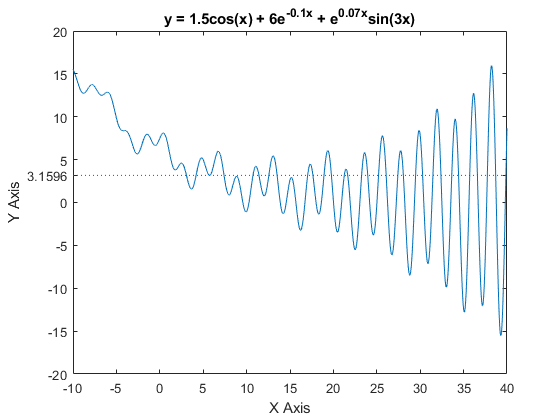

set(findobj('Type','line','Color','red'),'LineStyle',':')